# Лабораторная работа №1

Метод Лагранжа для равномерной сетки

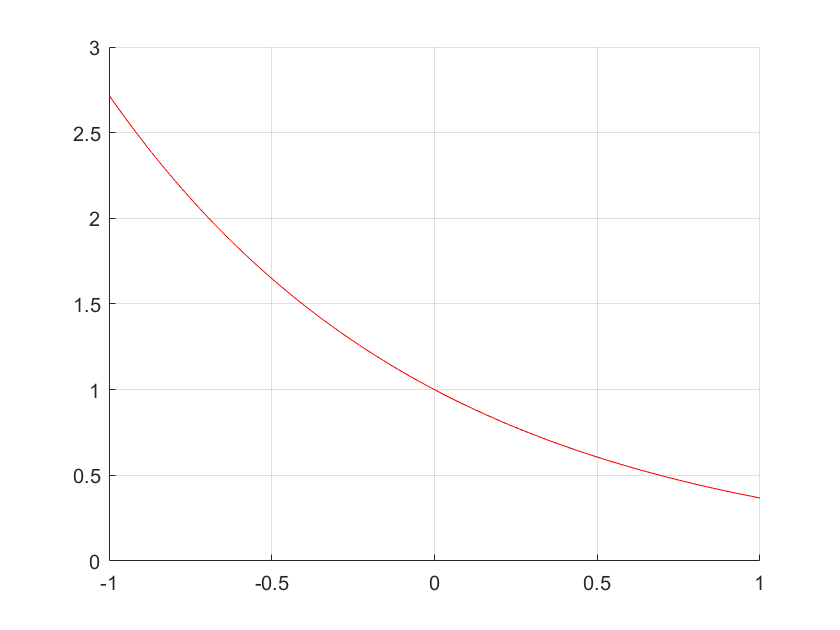

x = linspace(-1, 1, 50);
% x = [-1, 0, 1];
y = exp(-x);
xx = -1:0.01:1;
yy = lagr(x, y, xx);
figure
hold on;
grid on;
plot(x, y);
plot(xx, yy, 'Color', 'red');

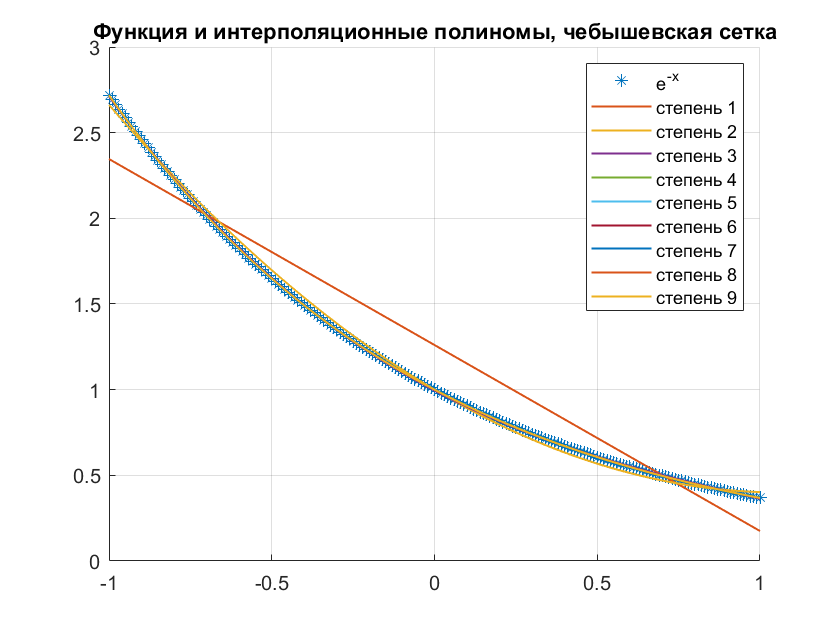

figure
hold on
grid on
xx = -1:0.01:1;
plot(xx, exp(-xx), '*');
str = 'e^{-x}';
for i = 2:10
    x = get_cheby_points([-1, 1], i);
%     x = linspace(-1, 1, i);
    y = exp(-x);
    xx = -1:0.01:1;
    yy = lagr(x, y, xx);
    plot(xx, yy, 'LineWidth', 1);
    str = [str, "степень " + num2str(i-1)];
end
legend(str);
title("Функция и интерполяционные полиномы, чебышевская сетка")

% title("Функция и интерполяционные полиномы")

Построение зависимости ошибки от количества точек на равномерной сетке для непрерывной функции.

n_max = 100;
 
f = @(x) exp(-x);
E = [];
parfor n = 2:n_max
    E(n) = get_err_cont(f, [-1, 1], n, "rvn");
end
disp('Равномерная сетка, непрерывная функция');

Равномерная сетка, непрерывная функция


figure
hold on
grid on
loglog(2:n_max, E(2:end));
Er = E;

Построение зависимости ошибки от количества точек на чебышевской сетке для непрерывной функции.

n_max = 100;
 
f = @(x) exp(-x);
E = [];
% points = logspace(0, 3, n_max);
parfor n = 2:n_max
    E(n) = get_err_cont(f, [-1, 1], n, "cheby");
end
disp('Чебышевская сетка, непрерывная функция');

Чебышевская сетка, непрерывная функция


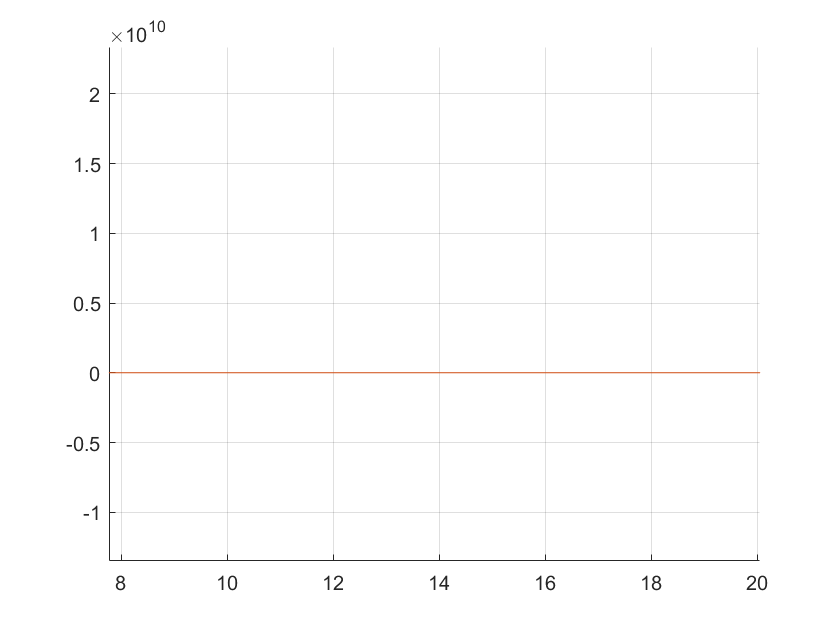

loglog(2:n_max, E(2:end));

Построение зависимости ошибки от количества точек на равномерной сетке для разрывной функции.

n_max = 100;
 
f = @(x) abs(x);
E = [];
parfor n = 2:n_max
    E(n) = get_err_cont(f, [-1, 1], n, "rvn");
end
disp('Равномерная сетка, разрывная функция');

Равномерная сетка, разрывная функция


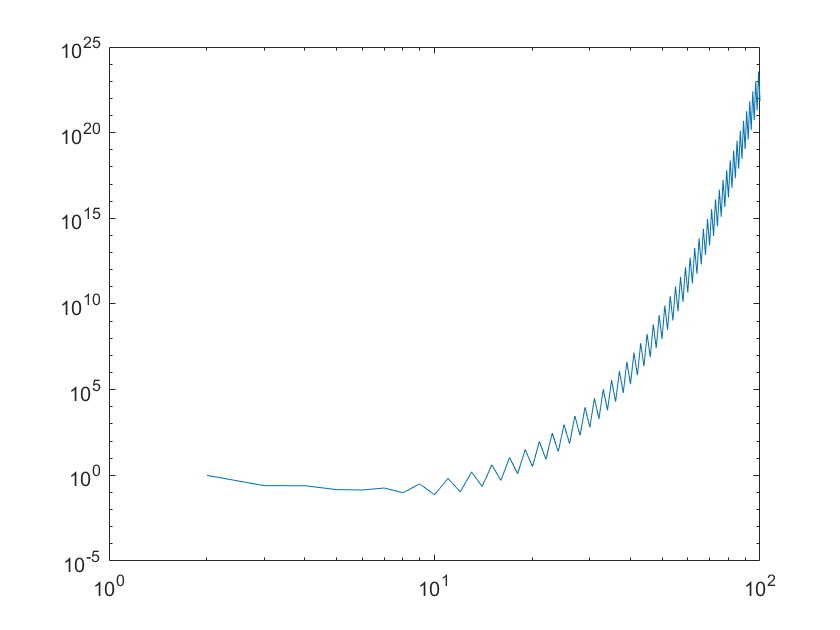

figure
loglog(2:n_max, E(2:end));

Err = E;

Построение зависимости ошибки от количества точек на чебышевской сетке для разрывной функции.

n_max = 100;
 
f = @(x) abs(x);
E = [];
parfor n = 2:n_max
    E(n) = get_err_cont(f, [-1, 1], n, "cheby");
end
disp('Чебышевская сетка, разрывная функция');

Чебышевская сетка, разрывная функция


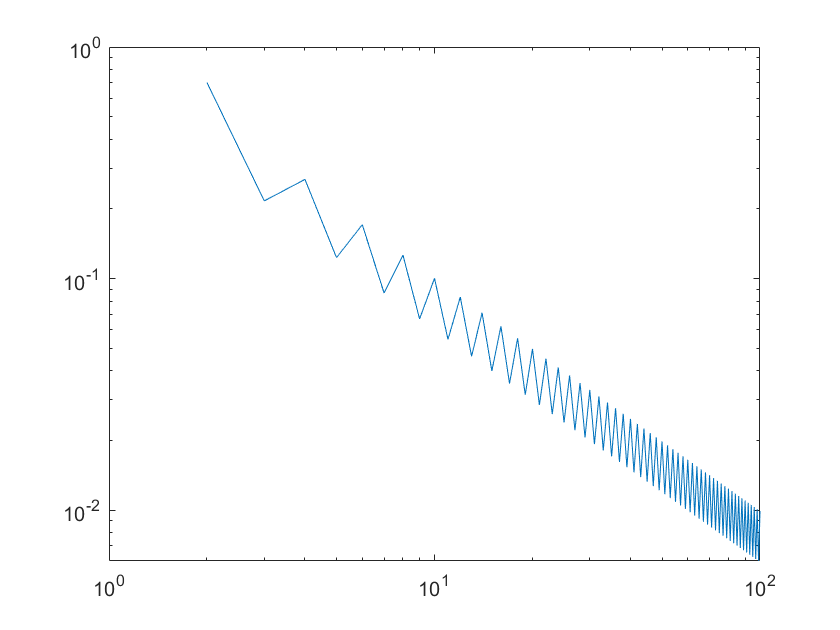

loglog(2:n_max, E(2:end));

function y0 = lagr(x, y, x0)
    y0 = zeros(size(x0));
    for j = 1:length(x0)
        N = length(x);
        yx = 0;
        for i = 1:N
            yx = yx + y(i)*mlt(x0(j), x, i)/mltd(x, i);
        end
        y0(j) = yx;
    end
end

function z = mlt(x0, x, j)
    z = 1;
    for i = 1:length(x)
        if i ~= j
            z = z.*(x0 - x(i));
        end
    end
end

function z = mltd(x, j)
    z = 1;
    for i = 1:length(x)
        if i ~= j
            z = z*(x(j) - x(i));
        end
    end
end

function delta = get_error(x_tr, x_pred)
    a = x_tr' - x_pred';
    a = abs(a);
    delta = max(a);
end

function eps = get_err_cont(f, dd, n, type_s)
    if type_s == "rvn"
        X = linspace(dd(1), dd(2), n);
        Y = f(X);
        xx = [];
%         for i = 2:length(X)
%             xx(i) = 0.5*(X(i)+X(i-1));
%         end
        xx = linspace(dd(1), dd(2), 100*n);
        yy = lagr(X, Y, xx);
        Y = f(xx);
        eps = get_error(Y, yy);
    elseif type_s == "cheby"
        syms t;
        X = get_cheby_points(dd, n);
        Y = f(X);
        xx = [];
%         for i = 2:length(X)
%             xx(i) = 0.5*(X(i)+X(i-1));
%         end
        xx = linspace(dd(1), dd(2), 100*n);
        yy = lagr(X, Y, xx);
        Y = f(xx);
        eps = get_error(Y, yy);
    end
end

function X = get_cheby_points(d, n)
    X = [];
    for i = 1:n
        X(i) = 0.5*(d(1)+d(2)) + 0.5*(d(2) - d(1))*cos((2*i-1)/(2*n)*pi);
    end
end